# Pendolo Invertito

Iniziamo settando i parametri del sistema ad alcuni valori iniziali:

clear;
clearvars;
%x,t,m,M,l,F
dt = (0:0.05:40);
m = 5;%kg
M = 20;%kg
l = 1;%m
g = 9.81; %m/s^2
F = 0;%N

Infine le condizioni iniziali e la precisione del risolutore:

x0 = [pi/6,0,0,2];% theta_0 = pi/6, velocità angolare = 0 posizione iniziale=0
% velocità iniziale 2 m/s
opts = odeset('RelTol',1e-8,'AbsTol',1e-10);

Chiamiamo ora il nostro ode45:

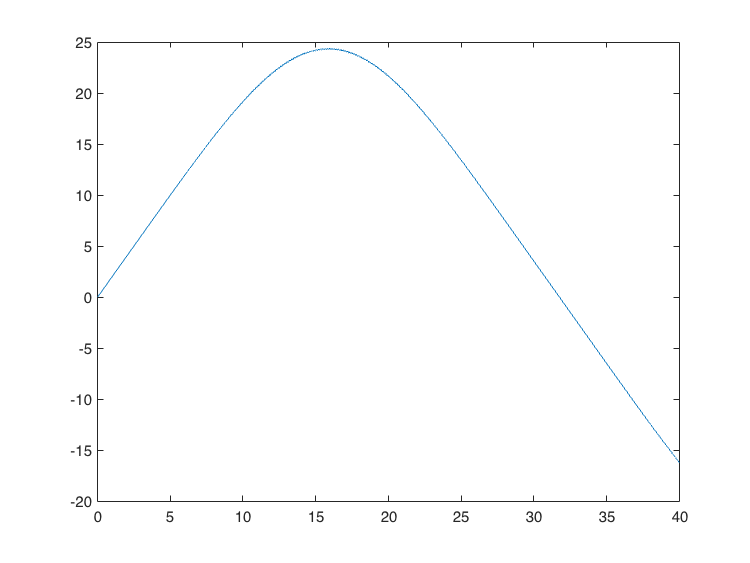

[t,x] = ode45(@(t,x)Inv_pend(x,t,m,M,l,F),dt,x0,opts);
figure;
plot(t,x(:,3))